%% Raman Nath Regime
%% Initialization 

units % load some common physical constants
m_Li6mol = 2*m_Li6;
aLi_12 = 982*a0;
add_Li = aLi_12*0.6;

omegax = 16*pi*2; % trap frequencies 
omegay = 74*pi*2;
omegaz = 68*pi*2;

% scale parameters
tscale = 1/(omegax); % time scale
rscale = sqrt(hbar/m_Li6mol/omegax); % spatial scale

% Lattice parameters defination
Wavelength = 1064*10^-9;
CrossingAngle = 15/180*pi; % cross angle for two ODT beams
D = Wavelength/(2*sin(CrossingAngle/2)); % Lattice period 4 micons
Erecoil = hbar^2*(pi/D)^2/(2*m_Li6mol); % recoil energy 250 Hz.

LatticePotential = 500; % lattice depth in unit of recoil energy
V = @(X,Y,Z) 0.5*(X.^2 ); % function representing the external potential (must have 3 arguments)


xmax = 1000*D/rscale; %  grid boundaries [-xmax,xmax]
N = 1000000; % number of grid points for coordinate grid

try
    x = gpuArray.linspace(-xmax,xmax,N);
    grid = grid1d(x);
catch
    grid = grid1d(xmax,N); % create a two-dimensional NxN grid object
end

task = GPEtask(grid,V); % initialize the GPE solver
task.Ntotal = 3000; % wave function normalization (total number of atoms)
% task.g = 4*pi*aLi/rscale/sqrt(2*pi/omegay*omegax); % nonlinear interaction constant
task.g = 1;

task.Xscale = rscale;
task.Tscale = tscale;
task.LatticeConstant = D;


%% Stationary state calculation

acc = 1e-3; % desired accuracy
% phi = task.groundstate_itp(tstep,acc,'tf'); % phi will contain calculated stationary state
[phi,mu,R] = task.groundstate_tf_harmonic(add_Li,omegax,omegay,omegaz);
task.g = 16*add_Li/(3*rscale* R(1).^2); % nonlinear interaction constant


%% switch on lattice for Deltat
Deltat = 20*10^-6/tscale; % total duration for simulation; (20 mico-seconds)
tstep = 2*10^-9/tscale; % time step for calculation; (20 ns)
steps_int = 10;  % number of intenal steps. (should be larger than 10 task.n_recalc)

task.init_state = phi;
task.show_image = 1; % show the solution on every precessing step


NmaxP = 249; % maximum mode of momentum to be analyzed

% function representing the external potential (must have 3 arguments)
Vlattice = @(X,Y,Z) LatticePotential*Erecoil/(hbar*omegax)*cos((pi/D)*X*rscale).^2; 
task.UpdatePotential(Vlattice);
task.history.MomentumDensity = [];
task.user_callback = @(x)task.FFTanalysis(0,NmaxP);
steps_ext = task.current_iter + Deltat/tstep/steps_int;

Split-step: iter - 1, mu - 3902.923, calc. time - 0.336 sec.; 0 mode Proportion: 1
Split-step: iter - 2, mu - 3902.923, calc. time - 0.569 sec.; 0 mode Proportion: 1
Split-step: iter - 3, mu - 3902.923, calc. time - 0.803 sec.; 0 mode Proportion: 1
Split-step: iter - 4, mu - 3902.923, calc. time - 1.034 sec.; 0 mode Proportion: 0.999
Split-step: iter - 5, mu - 3902.923, calc. time - 1.269 sec.; 0 mode Proportion: 0.999
Split-step: iter - 6, mu - 3902.923, calc. time - 1.505 sec.; 0 mode Proportion: 0.999
Split-step: iter - 7, mu - 3902.923, calc. time - 1.749 sec.; 0 mode Proportion: 0.998
Split-step: iter - 8, mu - 3902.923, calc. time - 1.976 sec.; 0 mode Proportion: 0.998
Split-step: iter - 9, mu - 3902.923, calc. time - 2.205 sec.; 0 mode Proportion: 0.997
Split-step: iter - 10, mu - 3902.923, calc. time - 2.435 sec.; 0 mode Proportion: 0.997
Split-step: iter - 11, mu - 3902.923, calc. time - 2.669 sec.; 0 mode Proportion: 0.996
Split-step: iter - 12, mu - 3902.923, calc. time - 2.

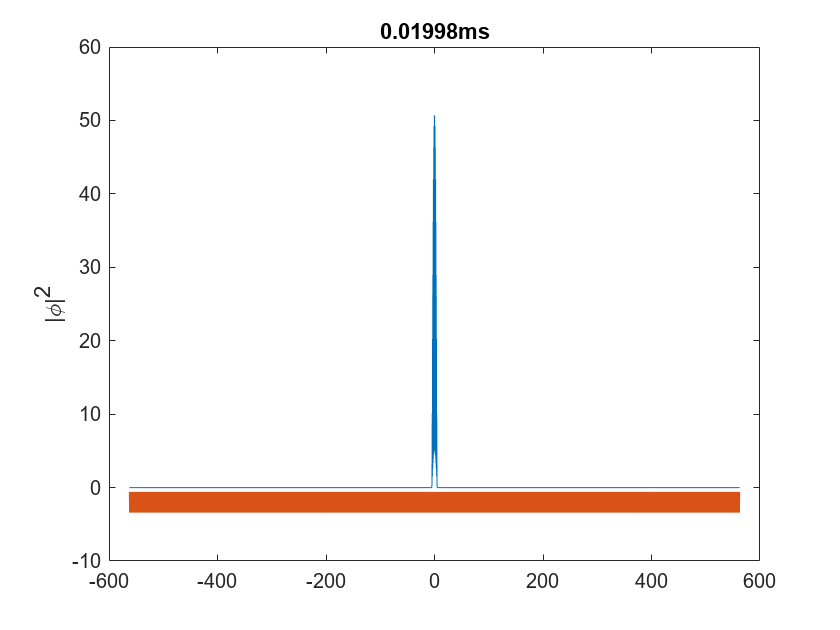

Split-step: iter - 999, mu - 3902.927, calc. time - 228.383 sec.; 0 mode Proportion: 0.0465



% start simulation
task.solve_split(tstep,steps_int,steps_ext); % run the calculation

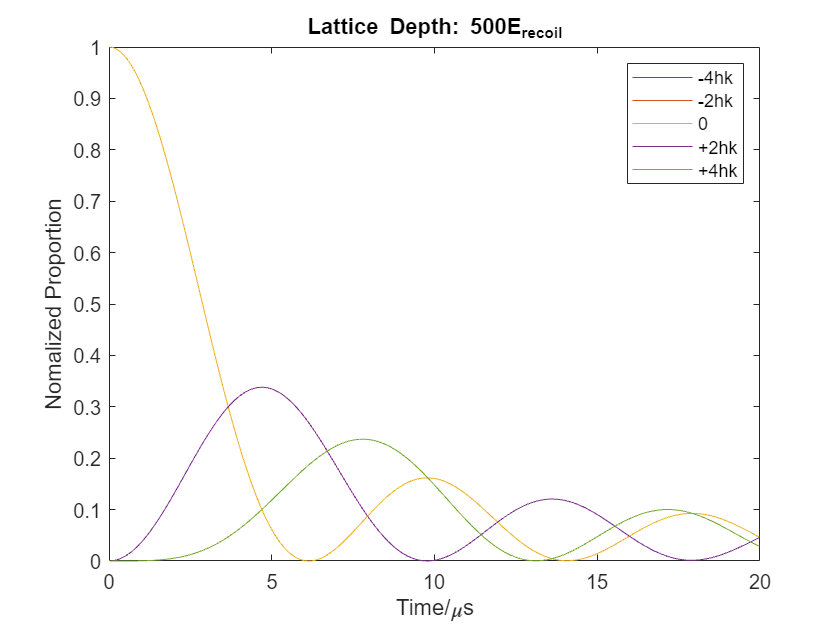


trange = (1:steps_ext)*tstep*steps_int*tscale;
plot(trange*10^6, task.history.MomentumDensity(:,NmaxP-1:NmaxP+3)')
xlabel('Time/\mus')
ylabel("Nomalized Proportion")
title(['Lattice Depth: ',num2str(LatticePotential),'E_{recoil}'])
legend('-4hk','-2hk','0','+2hk','+4hk')

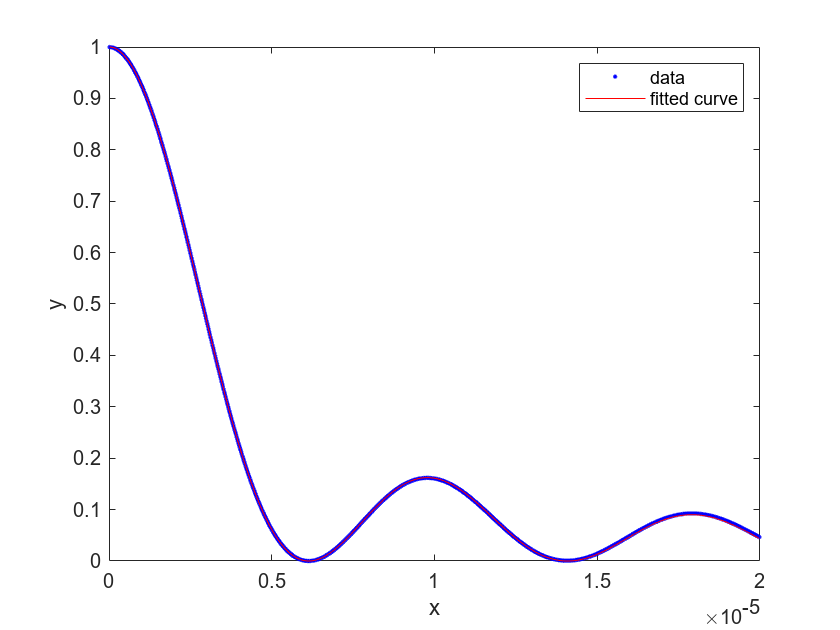

Tcoeffienct = 3.9184e+05

if  isgpuarray( task.history.MomentumDensity)
    Tcoeffienct = BesselFit(trange,gather(task.history.MomentumDensity(:,NmaxP+1)'),0)
else
Tcoeffienct = BesselFit(trange,task.history.MomentumDensity(:,NmaxP+1)',0)
end

Tcoef_theory = LatticePotential*Erecoil/2/hbar

Tcoef_theory = 3.9204e+05

 Raman-Nath regime?

For Raman-Nath regime


$$t_{\max } \frac{\sqrt{E_r U_0 }}{\hbar }<1$$


Deltat*tscale * sqrt(LatticePotential)*Erecoil/hbar

ans = 0.7013